
% 用拟合结果计算周期数 %

clear all;
close all;
colors=npg(10); % Ten basic colors 
maindir='\\Artemis-pc\e\Data\2024-04-20\Abs-476';
main_dir_0=maindir;
%load([maindir,'\population.mat']);
load([maindir,'\Fit.mat']);



T_173_sigma = T_sigma;   % 173 周期标准差
T_173 = T+0*T_173_sigma;   % 173 周期加权平均 ( ms )

T_171_sigma = T_sigma2;   % 171 周期标准差
T_171 = T2-0*T_171_sigma;   % 171 周期加权平均 ( ms )
%T_171_sigma = 0.065;   % 171 周期标准差
%T_171 = 43.228+0*T_171_sigma;   % 171 周期加权平均 ( ms )

tau_s = 8;   % s
tau_list = [0:0.5:40];   % ms
tau_ms = 3.12;   % ms

wait1 = 81;   % ms
wait2 = 21.6;   % ms

t_171_list = wait1+tau_s*1e3+tau_list+wait2*3;   % ms
t_173_list = tau_s*1e3+tau_list+wait2;   % ms

t_171 = wait1+tau_s*1e3+tau_ms+wait2*3;   % ms
t_173 = tau_s*1e3+tau_ms+wait2;   % ms

cycle171 = t_171/(T_171)

cycle171 = 378.0870

cycle173 = t_173/(T_173)

cycle173 = 512.7098


% 以上两数需手动修改 %



cycle171 = 1011.25;
cycle173 = 1380.75;

a171 = amp2;
a173 = amp*0.7;

f171 = cycle171/t_171;   % kHz
f173 = cycle173/t_173;   % kHz


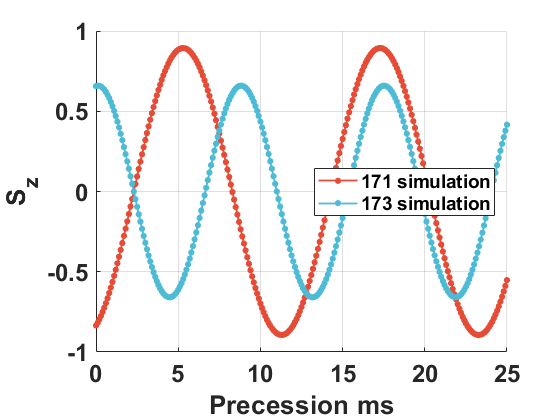


phase_171 = -a171*cos(2*pi*f171.*t_171_list);
phase_173 = -a173*cos(2*pi*f173.*t_173_list);
%phase_173 = -a173*cos(2*pi*cycle173 + 2*pi.*(tau_list-tau_ms)/T_173);

h1 = figure; hold on;
l1 = plot(tau_list,phase_171,'.-','Color',colors(1,:),'MarkerSize',16,'LineWidth',1.4);
l2 = plot(tau_list,phase_173,'.-','Color',colors(2,:),'MarkerSize',16,'LineWidth',1.4);

xlim([min(tau_list) max(tau_list)]);
ylim([-1 1]);
grid on;

xlabel('Precession ms');
ylabel('S_z');
legend('171 simulation','173 simulation','Location','best','FontSize',14);

set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold');
set(gcf,'Visible','on');


savefig(h1,[main_dir_0,'\Simulate_',num2str(tau_s),'s.fig']);
saveas(h1,[main_dir_0,'\Simulate_',num2str(tau_s),'s.png']);


save([main_dir_0,'\Simulate',num2str(tau_s),'s.mat']);

save([main_dir_0,'\cycle',num2str(tau_s),'s.mat'],"cycle171","cycle173");
